# Backtracking line search example

clear 
close all

% define funtion and gradient
f = @(x) x(1,:).^2 - 2.*x(2,:).*cos(x(1,:)) + 9;
g1 = @(x) 2.*x(1) + 2.*x(2).*sin(x(1));
g2 = @(x) 2.*sin(x(1));
g = @(x) [g1(x); g2(x)];

## **Plot the original function and linear function as step sie changes**

% select an initial point 
x0 = [1;1];
d = -g(x0);
a = 0:1e-3:1;
xw = x0 + a.*d;
rho = 0.1;
% define the stepsize function
f1 = f(xw);
% define linear step fucntion
f2 = f(x0)-rho.*a.*(d'*d);
plot(a, f1, 'DisplayName','f1')
hold on 
plot(a, f2, 'DisplayName','f2')


## Scatter the alpah of intertaions

scatter(0, f(x0+0), '')
x0 = [1;1];
d = -g(x0);
a = 1;
xw = x0 + a.*d;
rho = 0.1;
gam = 0.5;
f1 = f(xw);
f2 = f(x0)-rho.*a.*(d'*d);

while f1>f2
     scatter(a, f(x0+a.*d),'filled', 'SizeData', 50)
     a = gam*a
     xw = x0 + a.*d;
     f1 = f(xw);
     f2 = f(x0)-rho.*a.*(d'*d);
     
end

a = 0.5000

a = 0.2500

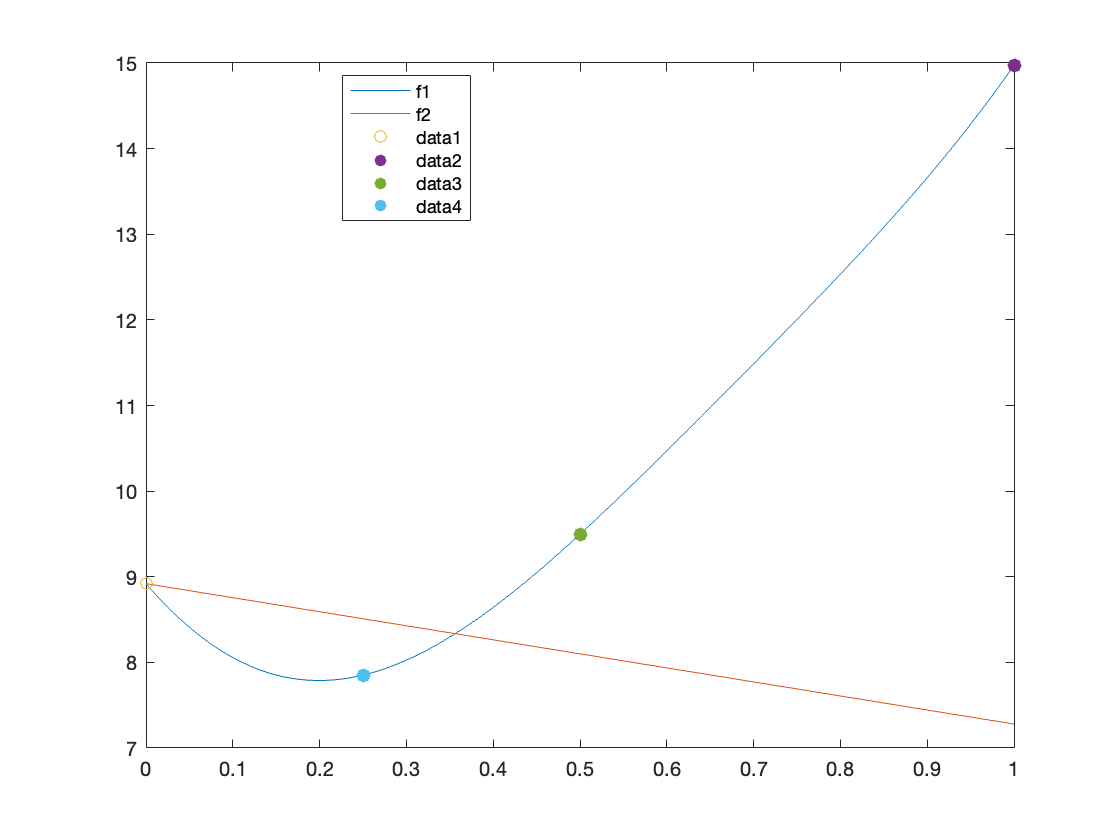

scatter(a, f(x0+a.*d),'filled', 'SizeData', 50)
legend('Location',"best")
hold off